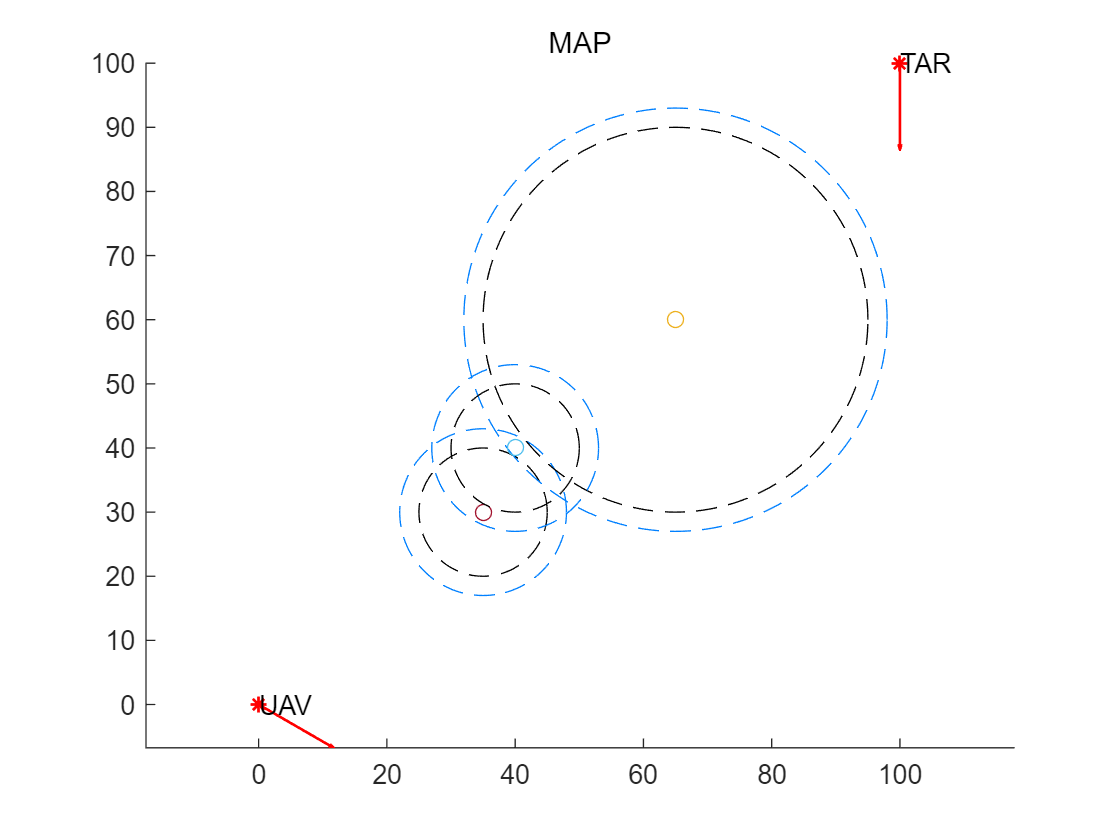

clear all
%% 定义函数输入
Start_Point = [0,0,-pi/6];
End_Point = [100,100,-pi/2];%[x,y,角度]
r=15;%最小转弯半径
Stepsize=0.01;%路径的生成间隔

sure=3;%保证安全的预留距离
% R=10+sure;
obs=[35,30,10+sure;
     65,60,30+sure;
     40,40,10+sure];%[x,y,障碍物的半径R]

figure(1)
Draw_map(Start_Point,End_Point,obs,sure);%绘制地图

hold off

%A*算法开始

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%初始节点
open={};
close={};
open_f=[];

%%节点[点的位置(出发点)，方向(1个)，f,g，无path]
node.point=Start_Point(1:2);
node.vtheta=Start_Point(3);
node.g=0;
node.f=node.g+obtain_h(node.point,End_Point(1:2));
close{end+1}=node;



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%产生初始路径

[param_all_start{1},param_best_start{1}] = Dubins_no_obs(Start_Point, End_Point,r,r,Stepsize);




%%判断所有的初始路径是否不碰撞
flag_all=obtain_flag_safe(1,param_all_start,obs);


% %%如果有安全的
% %%选择安全中最短的

[min_path,path_safe_flag,flag_min]=obtain_min_or_onlypath_from_safe(1,param_all_start,flag_all);
if flag_min~=0
    disp('Find Goal!!');
    disp(['min_path:',num2str(min_path)]);
    Draw_pathA(close,sure)
end



%%选出碰撞的障碍物n个（及其路径）
[path_num, obs_num] = find(flag_all == 0);%%第pah_num行，第obs_num列为0
[obs_to_avoid, ~, ~] = unique(obs_num);
%%生成避障路线n(转弯半径只有1种)*4===>n=0,则选择最优直达
%%初始节点[点的位置(起点)，方向，f,g,path]
for i=1:length(obs_to_avoid)
    [param_all{i},param_best{i}] = Dubins_obs(Start_Point,End_Point,obs(obs_to_avoid(i),1:2),r,r,obs(obs_to_avoid(i),3),Stepsize);
%     [param_all{2,i},param_best{2,i}] = Dubins_obs(Start_Point,End_Point,obs(obs_to_avoid(i),1:2),r,r,obs(obs_to_avoid(i),3),Stepsize);
end
%%param_all=>k列=K个障碍物==>每一个cell是一个1*4（4种路径）的结构体



%%检查避障路线的from_path=1,to_path=2是否碰撞
% %（从当前节点到下一节点）

flag_all=obtain_flag_safe(2,param_all,obs);

[min_path,path_safe_flag,flag_min]=obtain_min_or_onlypath_from_safe(2,param_all,flag_all);
%(路径数=需要躲避障碍物数*4)*障碍物数



%%选择不碰撞的路径，g=到起点的距离=path.1+path.2,h=直线距离？
%%节点[点的位置(2个=出发圆+障碍圆切入)，方向(1个)，f,g,path(2个=弧度+直线)]
[open_f,open]=update_open(path_safe_flag,param_all,End_Point,open_f,open,r);

%%选择最短节点

flag_min=find(open_f==min(open_f));

%%移除open，加入close
% open{flag_min}
close{end+1}=open{flag_min};
open{flag_min}={};
open_f(flag_min)=[];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%循环开始
%%生成无碰撞路径2(半径不同)*4

while 1
param_all={};
[param_all{1},param_best{1}] = Dubins_no_obs([close{end}.point(:,2)',close{end}.vtheta], End_Point,r,r,Stepsize);
[param_all{2},param_best{2}] = Dubins_no_obs([close{end}.point(:,2)',close{end}.vtheta], End_Point,close{end}.R,r,Stepsize);



%%判断所有的初始路径是否不碰撞(和自己碰撞直接排除)=>直接生成
flag_all=obtain_flag_safe(1,param_all,obs);

% %%如果有安全的
% %%选择安全中最短的
[min_path,path_safe_flag,flag_min]=obtain_min_or_onlypath_from_safe(1,param_all,flag_all);

if flag_min~=0
    disp('Find Goal!!');
    Draw_pathA(close,sure)
    break;
end

Find Goal!!


[path_num, obs_num] = find(flag_all == 0);
[obs_to_avoid, ~, ~] = unique(obs_num);

%%选出碰撞的障碍物(排除和自己的转弯圆碰撞)n个（及其路径）
for i=1:length(obs_to_avoid)
    if isequal(obs(i,1:2),close{end}.center(:,2)')
        flag_all(:,i)=1;
    end
end

[path_num, obs_num] = find(flag_all == 0);
[obs_to_avoid, ~, ~] = unique(obs_num);


%%%%%%%%%%%%%%%%%%确定具体的躲避障碍

%%生成避障路线n(转弯半径2种)*4===>n=0,则选择最优直达
%%初始节点[点的位置(起点)，方向，f,g,path]

for i=1:length(obs_to_avoid)
    [param_all{1,i},param_best{1,i}] = Dubins_obs([close{end}.point(:,2)',close{end}.vtheta],End_Point,obs(obs_to_avoid(i),1:2),r,r,obs(obs_to_avoid(i),3),Stepsize);
    [param_all{2,i},param_best{2,i}] = Dubins_obs([close{end}.point(:,2)',close{end}.vtheta],End_Point,obs(obs_to_avoid(i),1:2),close{end}.R,r,obs(obs_to_avoid(i),3),Stepsize);
end

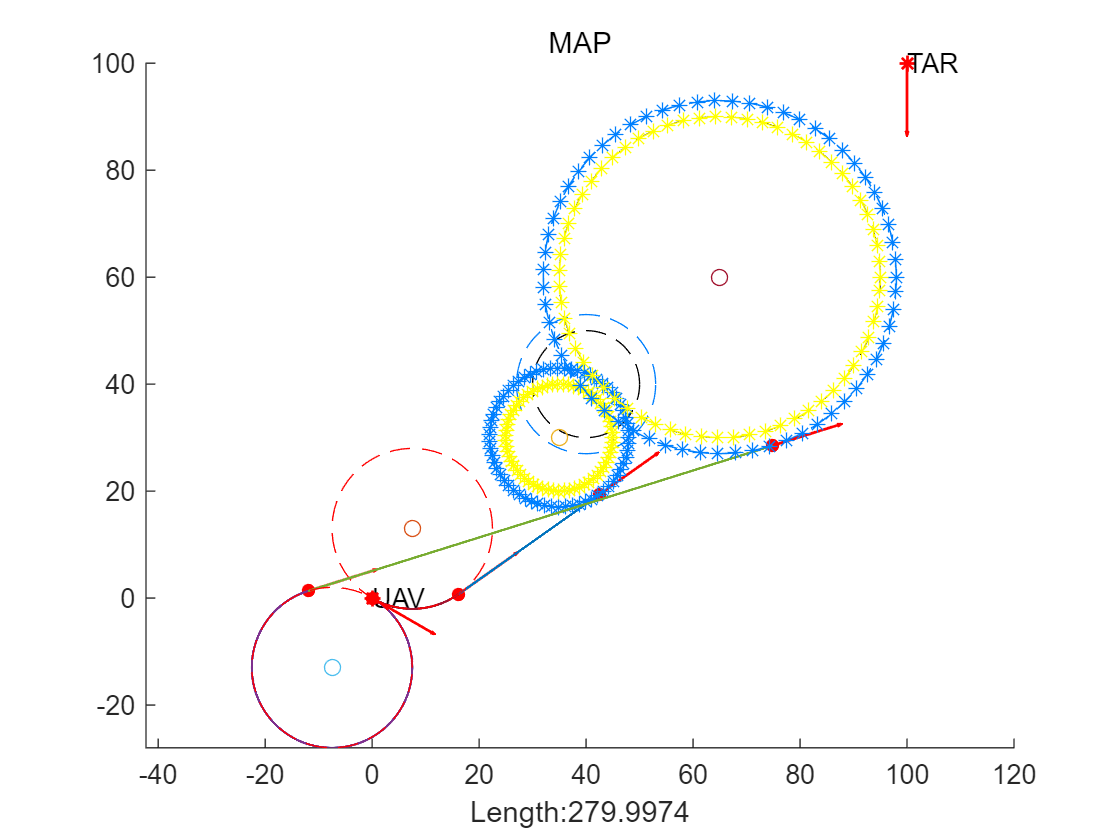



%检查1-2的安全
flag_all=obtain_flag_safe(2,param_all,obs);

%%如果有安全的

[min_path,path_safe_flag,flag_min]=obtain_min_or_onlypath_from_safe(2,param_all,flag_all);

% 
% % 判断条件并选择
% if flag_min.r~=0 && flag_min.R~=0
%     disp('Find Goal!!');
%     [minValue, index] = min([min_path.R,min_path.r]);
%     if index==1   
%         Draw_path(param_all(path_safe_flag.R(flag_min.R)),sure,1,3);
%     else 
%         Draw_path(param_all(path_safe_flag.r(flag_min.r)),sure,1,3);
%     end
% 
% elseif flag_min.r~=0
%     min_path=min_path.r;
%     Draw_path(param_all(path_safe_flag.r(flag_min.r)),sure,1,3);
% elseif flag_min.R~=0
%     min_path=min_path.R;
%     Draw_path(param_all(path_safe_flag.R(flag_min.R)),sure,1,3);
% end



%%选择不碰撞的路径，g=到起点的距离=path.1+path.2,h=直线距离？
%%节点[点的位置(2个=出发圆+障碍圆切入)，方向(1个)，f,g,path(2个=弧度+直线)]

[open_f,open]=update_open(path_safe_flag.r,param_all(1,:),End_Point,open_f,open,r);
[open_f,open]=update_open(path_safe_flag.R,param_all(2,:),End_Point,open_f,open,close{end}.R);



flag_min=find(open_f==min(open_f));

%%移除open，加入close
% open{flag_min}
close{end+1}=open{flag_min};
open{flag_min}={};
open_f(flag_min)=[];

Draw_pathA(close,sure)

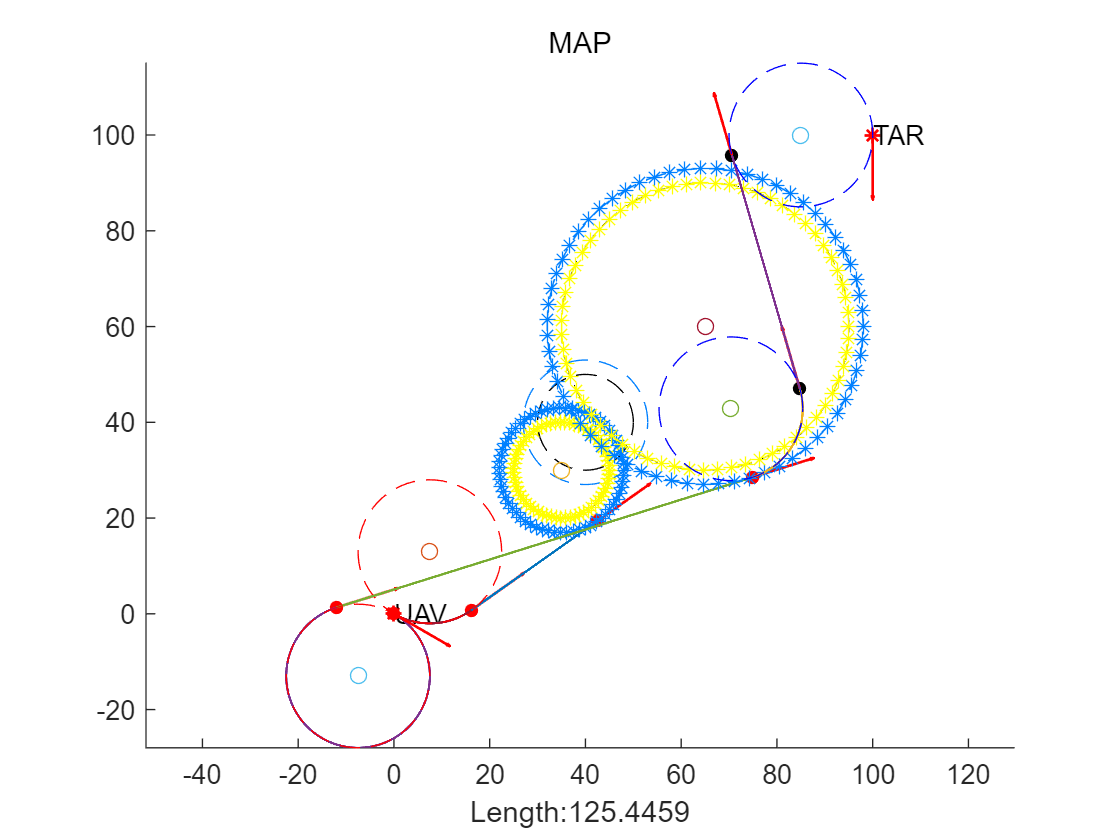


end
%%%%%%%%%%%%%%%%%循环结束

Draw_path(param_best{1},sure,1,2)
hold off


